## EXAMPLE 

Consider the four-bus power system shown in **Figure1**, it consists of four busbars with two generator and two loads connected  by five transmission lines. The impedance of the transmission lines are given in in per unit expressed on the same bases. It is assumed  all the buses have the same voltage magnitude $\left|V_1 \right|=\left|V_2 \right|=\left|V_3 \right|=\left|V_4 \right|=1\ldotp 0\;\textrm{pu}$, the bus 1 assumed the *slack* *bus*, as a consequence, $\theta_1 =0°$. $\theta_2$, $\theta_3$and $\theta_4$ are the unknown voltages angles. 

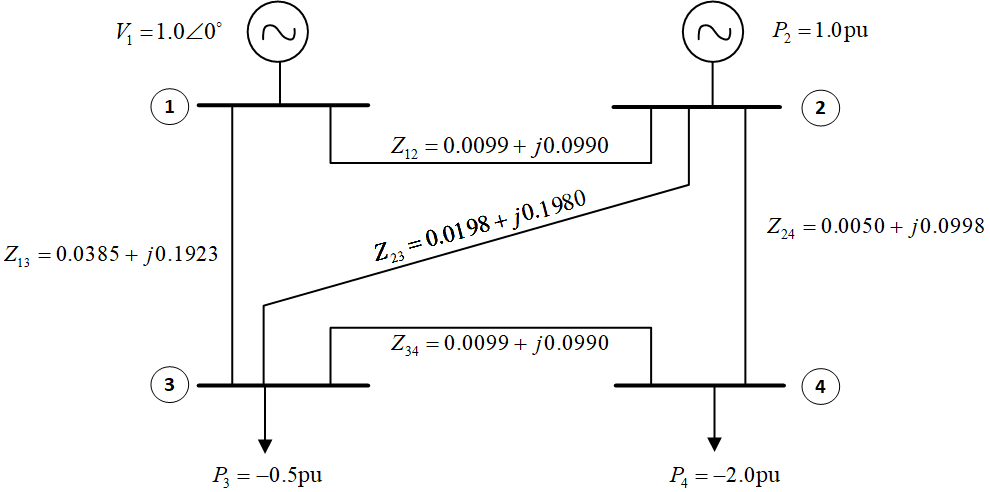                       

**Figure 1. Single-line diagram of the power system.    **     

***Procedure: ***

- Create a matrix containing the network connection and impedances of all transmission lines.

%         node i  node j     Z  =  R + jX
Zdata  = [   1       2     0.2 + 1.0*i;
             1       3     0.6 + 4.0*i;
             2       3     0.1 + 2.0*i;
             2       4     0.0 + 0.0*i;
             3       4     0.0 + 0.0*i]; 
nbus = max(max(Zdata(:,1)), max(Zdata(:,2)));   %total number of buses
nbr = length(Zdata(:,1));    %total number of branches

         2. The bus 1 is assumed as slack bus,  therefore its voltage angle is defined as $\delta_1 =0°$. On the other hand, the  voltage angles of bus 2, 3 and 4 are unknow, $\theta =\left\lbrack \begin{array}{ccc}
\theta_1  & \theta_2  & \theta_3 \;\;\;\;\theta_4 
\end{array}\right\rbrack$ .  Be aware all angles will be expressed in radians. 

theta = [0; NaN; NaN; NaN]

theta =      0
   NaN
   NaN
   NaN


       3. The active power in per unit at bus 1, 2, 3 and 4 is$\;\mathbf{P}=\left\lbrack \begin{array}{ccc}
P_1  & P_2  & P_3 \;\;\;P_4 
\end{array}\right\rbrack$. Since bus 1  is assumed as slack bus, $P_1$ is unknow. 

P = [NaN; -0.2; -0.4; 0]

P =        NaN
   -0.2000
   -0.4000
         0


        4.  Build the admittance matrix

Y = build_Y(Zdata)

Y =    0.2290 - 1.2060i  -0.1923 + 0.9615i  -0.0367 + 0.2445i   0.0000 + 0.0000i
  -0.1923 + 0.9615i      Inf - 1.4603i  -0.0249 + 0.4988i     -Inf + 0.0000i
  -0.0367 + 0.2445i  -0.0249 + 0.4988i      Inf - 0.7433i     -Inf + 0.0000i
   0.0000 + 0.0000i     -Inf + 0.0000i     -Inf + 0.0000i      Inf + 0.0000i


        5.  The suceptance matrix (**B**) is calculated  by taking the imaginary part of the admittance matrix ($\mathbf{Y}$):

B = imag(Y)

B =    -1.2060    0.9615    0.2445         0
    0.9615   -1.4603    0.4988         0
    0.2445    0.4988   -0.7433         0
         0         0         0         0


        6.  As bus 1 is considered as slack,  the first row of the active power injection vector is  disregarded. The first row and column of **B** are disregarded. 

P_reduced = P(2:nbus)

P_reduced =    -0.2000
   -0.4000
         0


B_reduced = B(2:nbus,2:nbus)

B_reduced =    -1.4603    0.4988         0
    0.4988   -0.7433         0
         0         0         0


      7.  Calculate the voltage angles $\theta_2$, $\theta_3$ and $\theta_4$  using  equation (9) as following:                                                                                                                                          

theta (2:4) = double((-B_reduced)\P_reduced)

theta =      0
   NaN
   NaN
   NaN


Please, be aware those angles are defined in radians.

     8. Compute the total active power provided by the slack bus using the following equation: 

$P_1$= $B_{11}$$\theta_1$+$B_{12}$$\theta_2$+...+$B_{1i}$$\theta_i$+$B_{1n}$$\theta_n$

P1 = double(-B(1,:)*theta)

P1 = NaN

P (1,1) = P1

P =        NaN
   -0.2000
   -0.4000
         0


      9. Perform the contingency analysis by disconnecting one transmission line at a time and computing voltages angles, the active power provided by the slack bus and the active power flow through the transmission lines. 

nC = 5;
bus = 1:1:nbus;
for k = 1:nC
    Zdata_contingency = Zdata;
    Zdata_contingency (k,3) = 0;
    Y = build_Y(Zdata_contingency);     %Step 4
    B = imag(Y);                        %Step 5
    P_reduced = P(2:nbus);              %Step 6
    B_reduced = B(2:nbus,2:nbus);
    theta (2:4) = double((-B_reduced)\P_reduced); %Step 7
    P1 = double(-B(1,:)*theta);    %Step 8
    P (1,1) = P1;

              Calculating the power flow through the transmission lines using the following equation: 


$$P_{\textrm{ij}} =\frac{\theta_i -\theta_j }{X_{\textrm{ij}} }$$


    for br = 1:nbr
        if br == k
           Pij(br,1) = 0;
        else 
           Pij(br,1) = (theta(Zdata_contingency(br,1))-theta(Zdata_contingency(br,2)))/imag(Zdata_contingency(br,3));
        end
    end
    fprintf('Contingency %i : Disconnecting transmission line %i-%i\n', k,Zdata_contingency(k,1), Zdata_contingency(k,2)) 
    name = {'Bus','Pi (pu)','Voltage angle (rad)'};
    table(bus', P, theta, 'VariableNames',name)
    name1 = {'From bus i','To bus j','Pij (pu)'};
    table(Zdata_contingency (:,1), Zdata_contingency (:,2), Pij, 'VariableNames',name1)
end

Contingency 1 : Disconnecting transmission line 1-2


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       NaN                0        
     2      -0.2              NaN        
     3      -0.4              NaN        
     4         0              NaN        


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2            0   
        1            3          NaN   
        2            3          NaN   
        2            4          NaN   
        3            4          NaN   


Contingency 2 : Disconnecting transmission line 1-3


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       NaN                0        
     2      -0.2              NaN        
     3      -0.4              NaN        
     4         0              NaN        


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2          NaN   
        1            3            0   
        2            3          NaN   
        2            4          NaN   
        3            4          NaN   


Contingency 3 : Disconnecting transmission line 2-3


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       NaN                 0       
     2      -0.2            -0.208       
     3      -0.4            -1.636       
     4         0               NaN       


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2         0.208  
        1            3         0.409  
        2            3             0  
        2            4           NaN  
        3            4           NaN  


Contingency 4 : Disconnecting transmission line 2-4


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       NaN                0        
     2      -0.2              NaN        
     3      -0.4              NaN        
     4         0              NaN        


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2          NaN   
        1            3          NaN   
        2            3          NaN   
        2            4            0   
        3            4          NaN   


Contingency 5 : Disconnecting transmission line 3-4


ans = 4×3 table
    Bus    Pi (pu)    Voltage angle (rad)
    ___    _______    ___________________

     1       NaN                0        
     2      -0.2              NaN        
     3      -0.4              NaN        
     4         0              NaN        


ans = 5×3 table
    From bus i    To bus j    Pij (pu)
    __________    ________    ________

        1            2          NaN   
        1            3          NaN   
        2            3          NaN   
        2            4          NaN   
        3            4            0   


### **Function to build Ybus **

The admittance matrix ($\mathbf{Y}$) must be created as following [2]:

                                           
$$\mathbf{Y}=\left\lbrack \begin{array}{cccccc}
Y_{11}  & Y_{12}  & \cdots  & Y_{1i}  & \cdots  & Y_{1n} \\
Y_{21}  & Y_{22}  & \cdots  & Y_{2i}  & \cdots  & Y_{2i} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
Y_{i1 }  & Y_{i2 }  & \cdots  & Y_{\textrm{ii}}  & \cdots  & Y_{\textrm{in}} \\
\vdots  & \vdots  &  & \vdots  &  & \vdots \\
Y_{n1 }  & Y_{n2 }  & \cdots  & Y_{\textrm{ni}}  & \cdots  & Y_{\textrm{nn}} 
\end{array}\right\rbrack \;\;\;\;\;\;\;i=1,2,\ldotp \ldotp \ldotp ,n\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$
                                              

where *n* represent the number of nodes in the nertwork. The diagonal element of each node is computed as the sum of admittances connected to it. It is known as the self-admitance:

                                                                   
$$Y_{\textrm{ii}} =\sum_{j=0}^n y_{\textrm{ij}} \;\;\;\;\;\;\;\;\;\;\;\;\;j\not= i\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$$
                                                                

The off-diagonal element is equal to the negative of the admitance between the nodes. It is know the mutual admittance or transfer admittance: 

                                              $Y_{\textrm{ij}} =Y_{\textrm{ji}} =-y_{\textrm{ij}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$                                                                          (3) 

Remember the admittance is computed as the inverse of the impedance: 

                                  $y_{\textrm{ik}} =\frac{1}{Z_{\textrm{ij}} }=\frac{1}{R_{\textrm{ij}} +jX_{\textrm{ij}} }=G_{\textrm{ij}} +jB_{\textrm{ij}\;\;\;} \left(4\right)$                                                           (4) 

function Y = build_Y(Z_data)
from = Z_data(:,1); to = Z_data(:,2);
nbr=length(Z_data(:,1)); nbus = max(max(from), max(to));
Z = Z_data(:,3);                          % Branch Impedance 
y= ones(nbr,1)./Z;                      % Branch Admittance

Y=zeros(nbus,nbus);          
for k = 1:nbr;   % Off-diagonal elements 
    if from(k) > 0 && to(k) > 0
    Y(from(k),to(k)) = Y(from(k),to(k)) - y(k);
    Y(to(k),from(k)) = Y(from(k),to(k));
    end
end
for n = 1:nbus       % Diagonal elements
    for k = 1:nbr
        if from(k) == n || to(k) == n
            Y(n,n) = Y(n,n) + y(k);
        else
        end
    end
end
end 